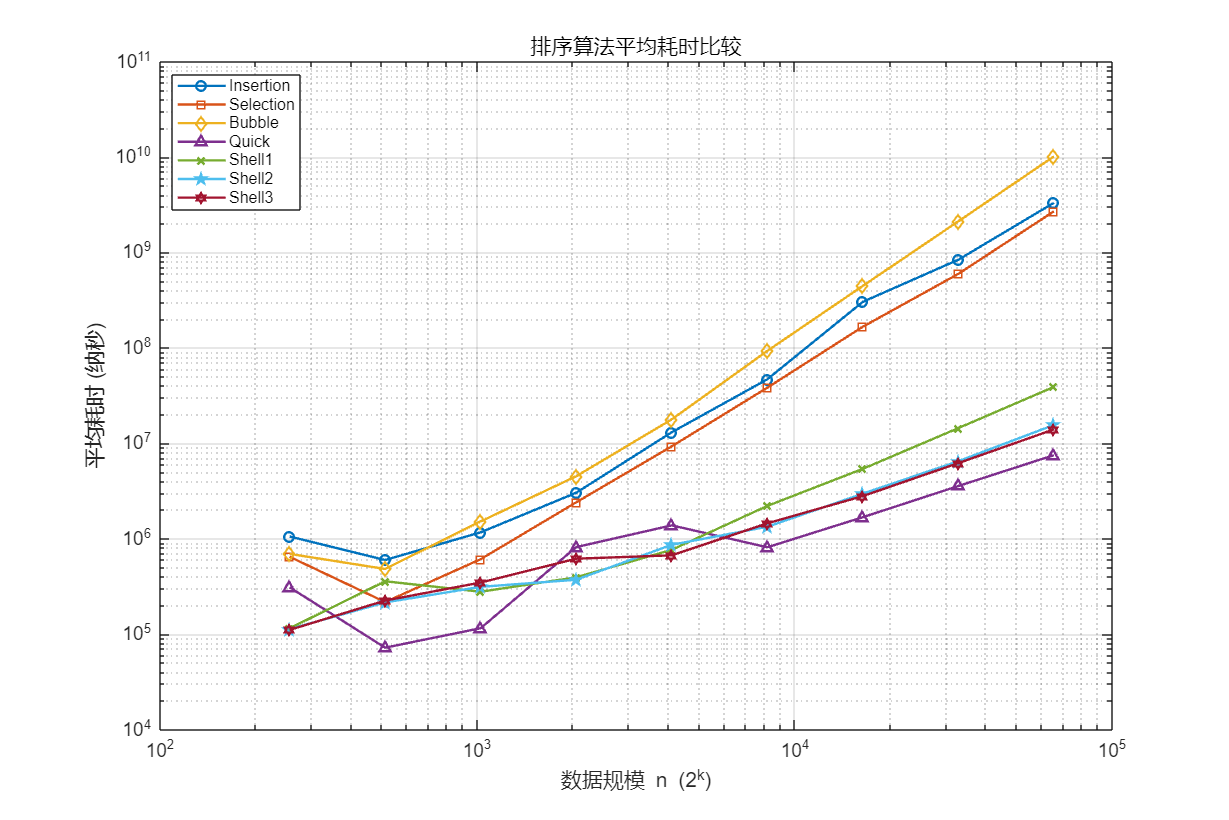

% ===========================
% 原始数据
% ===========================
n = [256 512 1024 2048 4096 8192 16384 32768 65536];

Insertion = [1055120 598100 1166420 3031620 13065700 46855120 303996900 840341380 3316836640];
Selection = [646480 216680 609920 2405920 9296760 38262260 166651400 597083060 2701324600];
Bubble = [693300 481600 1519060 4516740 17821120 92957220 446861160 2123296680 10168984160];
Quick = [309260 72100 115340 816640 1379500 813040 1681160 3568260 7512020];
Shell1 = [115060 357780 278120 393760 765840 2205680 5400060 14440480 39036000];
Shell2 = [112920 214720 312880 371380 864000 1333920 2966840 6498000 15565860];
Shell3 = [110720 224660 347160 617220 669540 1449180 2796480 6203560 13992740];

% ===========================
% 主图：7条算法比较（双对数）
% ===========================
figure('Position', [100, 100, 1200, 800]);
loglog(n, Insertion, '-o', 'LineWidth', 1.5); hold on;
loglog(n, Selection, '-s', 'LineWidth', 1.5);
loglog(n, Bubble, '-d', 'LineWidth', 1.5);
loglog(n, Quick, '-^', 'LineWidth', 1.5);
loglog(n, Shell1, '-x', 'LineWidth', 1.5);
loglog(n, Shell2, '-p', 'LineWidth', 1.5);
loglog(n, Shell3, '-h', 'LineWidth', 1.5);

grid on;
xlabel('数据规模 n (2^k)', 'FontSize', 12);
ylabel('平均耗时 (纳秒)', 'FontSize', 12);
title('排序算法平均耗时比较', 'FontSize', 14);
legend({'Insertion','Selection','Bubble','Quick','Shell1','Shell2','Shell3'}, ...
    'Location', 'northwest', 'FontSize', 10);
set(gca, 'FontSize', 12);

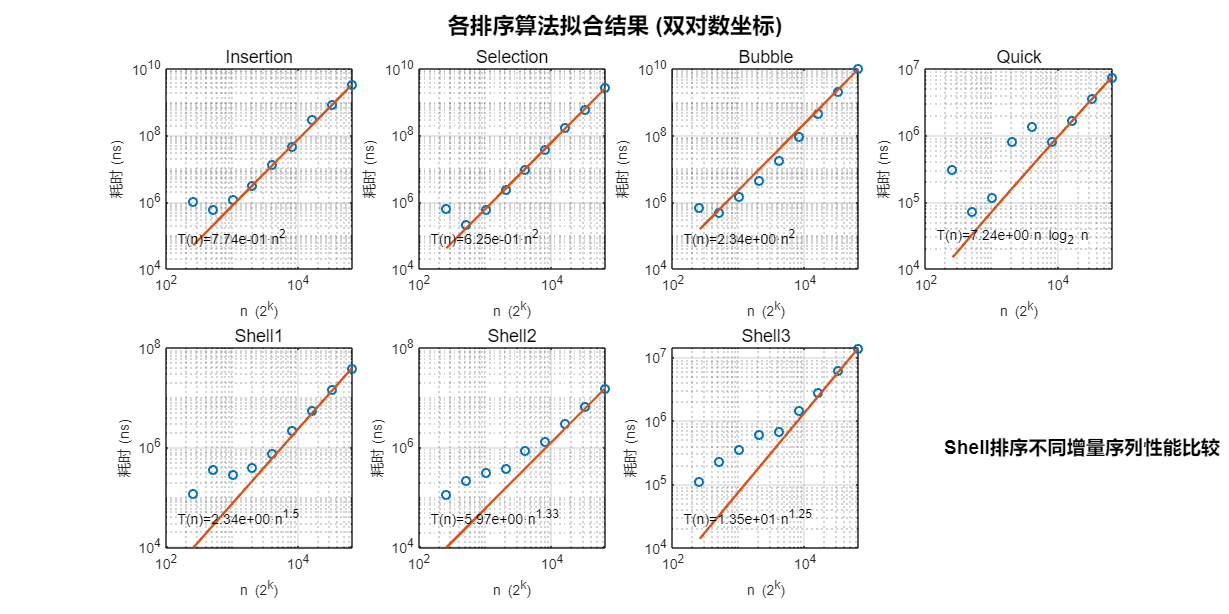


% ===========================
% 拟合函数定义
% ===========================
f_n2 = @(a, n) a .* n.^2;
f_quick = @(a, n) a .* n .* log2(n);
f_shell1 = @(a, n) a .* n.^(1.5);
f_shell2 = @(a, n) a .* n.^(4/3);
f_shell3 = @(a, n) a .* n.^(1.25);

% ===========================
% 拟合系数
% ===========================
a_insertion = fminsearch(@(a) norm(f_n2(a, n) - Insertion), 1e-6);
a_selection = fminsearch(@(a) norm(f_n2(a, n) - Selection), 1e-6);
a_bubble    = fminsearch(@(a) norm(f_n2(a, n) - Bubble), 1e-6);
a_quick     = fminsearch(@(a) norm(f_quick(a, n) - Quick), 1e-6);
a_shell1    = fminsearch(@(a) norm(f_shell1(a, n) - Shell1), 1e-6);
a_shell2    = fminsearch(@(a) norm(f_shell2(a, n) - Shell2), 1e-6);
a_shell3    = fminsearch(@(a) norm(f_shell3(a, n) - Shell3), 1e-6);

% ===========================
% 拼接子图：2×4
% ===========================
figure('Position',[100,100,1400,700]);

algorithms = {
    'Insertion', Insertion, f_n2, a_insertion, 'n^2';
    'Selection', Selection, f_n2, a_selection, 'n^2';
    'Bubble', Bubble, f_n2, a_bubble, 'n^2';
    'Quick', Quick, f_quick, a_quick, 'n log_2 n';
    'Shell1', Shell1, f_shell1, a_shell1, 'n^{1.5}';
    'Shell2', Shell2, f_shell2, a_shell2, 'n^{1.33}';
    'Shell3', Shell3, f_shell3, a_shell3, 'n^{1.25}';
};

for i = 1:size(algorithms,1)
    subplot(2,4,i);
    algo_name = algorithms{i,1};
    data_y = algorithms{i,2};
    func = algorithms{i,3};
    a = algorithms{i,4};
    order_str = algorithms{i,5};

    % 绘图
    loglog(n, data_y, 'o', 'MarkerSize', 5, 'LineWidth', 1.2); hold on;
    loglog(n, func(a, n), '-', 'LineWidth', 1.5);
    grid on;

    xlabel('n (2^k)', 'FontSize', 9);
    ylabel('耗时 (ns)', 'FontSize', 9);
    title(algo_name, 'FontSize', 11);

    % 显示拟合函数
    txt = sprintf('T(n)=%.2e·%s', a, order_str);
    text(0.05, 0.15, txt, 'Units','normalized', 'FontSize',9, 'Color','k');
end

% 调整布局（第八格空出来）
subplot(2,4,8);
axis off;
text(0.1,0.5,'Shell排序不同增量序列性能比较',...
    'FontSize',12,'FontWeight','bold');

sgtitle('各排序算法拟合结果 (双对数坐标)', 'FontSize', 14, 'FontWeight','bold');